# Avion - taller1 corte2

Asignacion de Polos

clear all
clc

%%Matrices
A = [0 1 0;0 -0.2 0;5 0 0]

A =          0    1.0000         0
         0   -0.2000         0
    5.0000         0         0


B = [0; 0.5; 0]

B =          0
    0.5000
         0


C = [0 0 1]

C =      0     0     1


D = 0

D = 0

[num,den] = ss2tf(A,B,C,D) 

num =          0         0         0    2.5000


den =     1.0000    0.2000         0         0


TF=tf(num,den)

TF =
 
       2.5
  -------------
  s^3 + 0.2 s^2
 
Continuous-time transfer function.
Model Properties


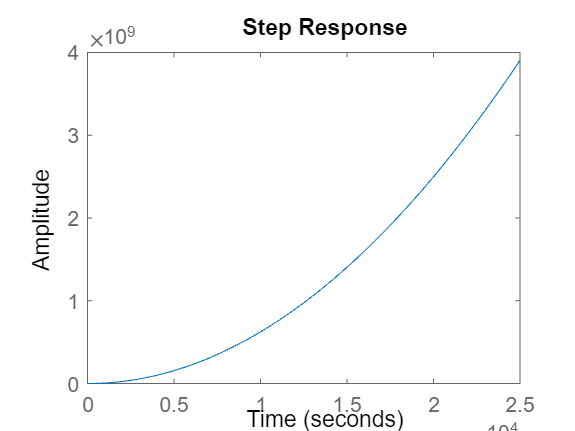

step(TF)

syms s k1 k2 k3 ki
k=[k1 k2 k3]

$$k = \left(\begin{array}{ccc} k_{1} & k_{2} & k_{3} \end{array}\right)$$

sI = s*eye(4)

$$sI = \left(\begin{array}{cccc} s & 0 & 0 & 0\\ 0 & s & 0 & 0\\ 0 & 0 & s & 0\\ 0 & 0 & 0 & s \end{array}\right)$$

Bk= B*k

$$Bk = \left(\begin{array}{ccc} 0 & 0 & 0\\ \frac{k_{1}}{2} & \frac{k_{2}}{2} & \frac{k_{3}}{2}\\ 0 & 0 & 0 \end{array}\right)$$

A_Bk = A-Bk

$$A\_Bk = \left(\begin{array}{ccc} 0 & 1 & 0\\ -\frac{k_{1}}{2} & -\frac{k_{2}}{2}-\frac{1}{5} & -\frac{k_{3}}{2}\\ 5 & 0 & 0 \end{array}\right)$$

B_ki= B*[ki]

$$B\_ki = \left(\begin{array}{c} 0\\ \frac{\mathrm{ki}}{2}\\ 0 \end{array}\right)$$


A_asq=[A-Bk B_ki;
    -C 0]

$$A\_asq = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ -\frac{k_{1}}{2} & -\frac{k_{2}}{2}-\frac{1}{5} & -\frac{k_{3}}{2} & \frac{\mathrm{ki}}{2}\\ 5 & 0 & 0 & 0\\ 0 & 0 & -1 & 0 \end{array}\right)$$


sI_A_Bk = sI-A_asq

$$sI\_A\_Bk = \left(\begin{array}{cccc} s & -1 & 0 & 0\\ \frac{k_{1}}{2} & \frac{k_{2}}{2}+s+\frac{1}{5} & \frac{k_{3}}{2} & -\frac{\mathrm{ki}}{2}\\ -5 & 0 & s & 0\\ 0 & 0 & 1 & s \end{array}\right)$$

PC_0 = det(sI_A_Bk)

$$PC\_0 = \frac{5\,\mathrm{ki}}{2}+\frac{5\,k_{3}\,s}{2}+\frac{k_{1}\,s^{2}}{2}+\frac{k_{2}\,s^{3}}{2}+\frac{s^{3}}{5}+s^{4}$$

PC=vpa(fliplr(coeffs(PC_0,s)),3)

$$PC = \left(\begin{array}{ccccc} 1.0 & 0.5\,k_{2}+0.2 & 0.5\,k_{1} & 2.5\,k_{3} & 2.5\,\mathrm{ki} \end{array}\right)$$

zeta = 1

zeta = 1

ts = 30

ts = 30

wn = 4/(ts*zeta)

wn = 0.1333

betha = 10

betha = 10

PD_0 = ((s^2)+2*zeta*wn*s+wn^2)*(s+betha*zeta*wn)*(s+betha*zeta*wn)

$$PD\_0 = {\left(s+\frac{4}{3}\right)}^{2}\,\left(s^{2}+\frac{4\,s}{15}+\frac{4}{225}\right)$$

PD=vpa(fliplr(coeffs(PD_0,s)),3)

$$PD = \left(\begin{array}{ccccc} 1.0 & 2.93 & 2.51 & 0.521 & 0.0316 \end{array}\right)$$

f0=vpa(PC(1)==PD(1),3)

$$f0 = 1.0=1.0$$

f1=vpa(PC(2)==PD(2),3)

$$f1 = 0.5\,k_{2}+0.2=2.93$$

f2=vpa(PC(3)==PD(3),3)

$$f2 = 0.5\,k_{1}=2.51$$

f3=vpa(PC(4)==PD(4),3)

$$f3 = 2.5\,k_{3}=0.521$$

f4=vpa(PC(5)==PD(5),3)

$$f4 = 2.5\,\mathrm{ki}=0.0316$$

solucion=solve(f1,f2,f3,f4)

solucion = struct with fields:
    k1: 5.0133333333069458603858947753906
    k2: 5.4666666666962555609643459320068
    k3: 0.20859259259304963052272796630859
    ki: 0.012641975308724795468151569366455


k1 = double(round(solucion.k1,3))

k1 = 5.0130

k2 = double(round(solucion.k2,3))

k2 = 5.4670

k3 = double(round(solucion.k3,3))

k3 = 0.2090

ki = double(round(solucion.ki,3))

ki = 0.0130

Matriz Transformacion con accion integral

disp('Matriz de Transformacion')

Matriz de Transformacion


A_t = [0 1 0 0; 
    0 -0.2 0 0; 
    5 0 0 0;
    0 0 -1 0]

A_t =          0    1.0000         0         0
         0   -0.2000         0         0
    5.0000         0         0         0
         0         0   -1.0000         0


B_t = [0; 0.5; 0; 0]

B_t =          0
    0.5000
         0
         0


C_t = [0 0 1]

C_t =      0     0     1


D = 0

D = 0


sI_t = s*eye(4)

$$sI\_t = \left(\begin{array}{cccc} s & 0 & 0 & 0\\ 0 & s & 0 & 0\\ 0 & 0 & s & 0\\ 0 & 0 & 0 & s \end{array}\right)$$

sI_t_At = sI_t-A_t

$$sI\_t\_At = \left(\begin{array}{cccc} s & -1 & 0 & 0\\ 0 & s+\frac{1}{5} & 0 & 0\\ -5 & 0 & s & 0\\ 0 & 0 & 1 & s \end{array}\right)$$

PC_t0 = det(sI_t_At)

$$PC\_t0 = \frac{s^{3}\,\left(5\,s+1\right)}{5}$$

PC_T=vpa(fliplr(coeffs(PC_t0,s)),3)

$$PC\_T = \left(\begin{array}{cc} 1.0 & 0.2 \end{array}\right)$$

Con_t = [B_t A_t*B_t (A_t)^2*B_t (A_t)^3*B_t]

Con_t =          0    0.5000   -0.1000    0.0200
    0.5000   -0.1000    0.0200   -0.0040
         0         0    2.5000   -0.5000
         0         0         0   -2.5000


syms a1 a2
a1 = 0.2

a1 = 0.2000

a2 = 0

a2 = 0

a3 = 0

a3 = 0

M_t = [a3 a2 a1 1;
    a2 a1 1 0;
    a1 1 0 0;
    1 0 0 0]

M_t =          0         0    0.2000    1.0000
         0    0.2000    1.0000         0
    0.2000    1.0000         0         0
    1.0000         0         0         0


T_t = Con_t*M_t

T_t =          0         0    0.5000         0
         0         0         0    0.5000
         0    2.5000         0         0
   -2.5000         0         0         0


T_t_inv = inv(T_t)

T_t_inv =          0         0         0   -0.4000
         0         0    0.4000         0
    2.0000         0         0         0
         0    2.0000         0         0


%%%%%%%%%%
PC_T=vpa(fliplr(coeffs(PC_t0,s)),3)

$$PC\_T = \left(\begin{array}{cc} 1.0 & 0.2 \end{array}\right)$$

PD=vpa(fliplr(coeffs(PD_0,s)),3)          

$$PD = \left(\begin{array}{ccccc} 1.0 & 2.93 & 2.51 & 0.521 & 0.0316 \end{array}\right)$$


K_t = [0.0316-0 0.521-0 2.51-0 2.93-0.2]*T_t_inv  %% CAMBIA

K_t =     5.0200    5.4600    0.2084   -0.0126


Ackerman

%% Se reemplaza en el deseado
MI = [1 0 0 0;
      0 1 0 0;
      0 0 1 0;
      0 0 0 1]

MI =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


phi_A = (A_t^4)+(2.93*A_t^3)+(2.51*A_t^2)+(0.521*A_t)+(0.0316*MI) %% CAMBIA

phi_A =     0.0316    0.1282         0         0
         0    0.0060         0         0
    2.6050    9.8200    0.0316         0
  -12.5500  -13.6500   -0.5210    0.0316


 K_ack = [0 0 0 1]*(inv(Con_t))*phi_A

K_ack =     5.0200    5.4600    0.2084   -0.0126


Ganancias

 %% Asignacion de Polos
 K_polos = [k1 k2 k3 ki]

K_polos =     5.0130    5.4670    0.2090    0.0130


 %% Matriz T
 K_t

K_t =     5.0200    5.4600    0.2084   -0.0126


 %% Ackerman
 K_ack

K_ack =     5.0200    5.4600    0.2084   -0.0126


**2) Observador**

%%Observador
syms L1 L2 L3
L=[L1;L2; L3]

$$L = \left(\begin{array}{c} L_{1}\\ L_{2}\\ L_{3} \end{array}\right)$$

A_LC= A-(L*C)

$$A\_LC = \left(\begin{array}{ccc} 0 & 1 & -L_{1}\\ 0 & -\frac{1}{5} & -L_{2}\\ 5 & 0 & -L_{3} \end{array}\right)$$

sI_obs = s*eye(3)

$$sI\_obs = \left(\begin{array}{ccc} s & 0 & 0\\ 0 & s & 0\\ 0 & 0 & s \end{array}\right)$$

disp('Calculos del Observador')

Calculos del Observador


PL_0=vpa(det(sI_obs-A_LC),3)

$$PL\_0 = L_{1}+5.0\,L_{2}+5.0\,L_{1}\,s+0.2\,L_{3}\,s+L_{3}\,s^{2}+0.2\,s^{2}+s^{3}$$

PL_1 = collect(expand(det(s*eye(3)-A_LC)),s)

$$PL\_1 = s^{3}+\left(L_{3}+\frac{1}{5}\right)\,s^{2}+\left(5\,L_{1}+\frac{L_{3}}{5}\right)\,s+L_{1}+5\,L_{2}$$

PL=vpa(fliplr(coeffs(PL_0,s)),3)

$$PL = \left(\begin{array}{cccc} 1.0 & L_{3}+0.2 & 5.0\,L_{1}+0.2\,L_{3} & L_{1}+5.0\,L_{2} \end{array}\right)$$

zeta = 1

zeta = 1

ts = 30/10 %% Debe ser mas rapido que el sistema controlado

ts = 3

wn = 4/(ts*zeta)

wn = 1.3333

betha = 10

betha = 10

PD_0 = ((s^2)+2*zeta*wn*s+wn^2)*(s+betha*zeta*wn)

$$PD\_0 = \left(s+\frac{40}{3}\right)\,\left(s^{2}+\frac{8\,s}{3}+\frac{16}{9}\right)$$

PD=fliplr(coeffs(PD_0,s))

$$PD = \left(\begin{array}{cccc} 1 & 16 & \frac{112}{3} & \frac{640}{27} \end{array}\right)$$

f0=vpa(PL(1)==PD(1),3)

$$f0 = 1.0=1.0$$

f1=vpa(PL(2)==PD(2),3)

$$f1 = L_{3}+0.2=16.0$$

f2=vpa(PL(3)==PD(3),3)

$$f2 = 5.0\,L_{1}+0.2\,L_{3}=37.3$$

f3=vpa(PL(4)==PD(4),3)

$$f3 = L_{1}+5.0\,L_{2}=23.7$$

solucion=solve(f1,f2,f3)

solucion = struct with fields:
    L1: 6.8346666666023083962500096426223
    L2: 3.373807407444424461573362329288
    L3: 15.79999999999927240423858165741


L1 = double(round(solucion.L1,3))

L1 = 6.8350

L2 = double(round(solucion.L2,3))

L2 = 3.3740

L3 = double(round(solucion.L3,3))

L3 = 15.8000

**OBSERVADOR ACKERMAN**

Con_obs_po = [C;C*A;C*A^2]

Con_obs_po =      0     0     1
     5     0     0
     0     5     0


Mi_obs = [1 0 0;0 1 0; 0 0 1]

Mi_obs =      1     0     0
     0     1     0
     0     0     1


phi_A_obs = (A^3)+(16*A^2)+(37.3*A)+(23.7*Mi_obs)

phi_A_obs =    23.7000   34.1400         0
         0   16.8720         0
  186.5000   79.0000   23.7000


L_obs_Ack = phi_A_obs*inv(Con_obs_po)*[0;0;1]

L_obs_Ack =     6.8280
    3.3744
   15.8000


**OBSERVADOR MATRIZ T**

PC_T=vpa(fliplr(coeffs(PC_t0,s)),4)

$$PC\_T = \left(\begin{array}{cc} 1.0 & 0.2 \end{array}\right)$$

PD=vpa(fliplr(coeffs(PD_0,s)),4)

$$PD = \left(\begin{array}{cccc} 1.0 & 16.0 & 37.33 & 23.7 \end{array}\right)$$

a1 =0.2

a1 = 0.2000

a2 = 0

a2 = 0

W_obs=[a1 a2 1;
    a2 1 0;
    1 0 0]

W_obs =     0.2000         0    1.0000
         0    1.0000         0
    1.0000         0         0


T_t = W_obs*Con_obs_po

T_t =          0    5.0000    0.2000
    5.0000         0         0
         0         0    1.0000


T_t_inv = inv(T_t)

T_t_inv =          0    0.2000         0
    0.2000         0   -0.0400
         0         0    1.0000


L_t = T_t_inv*[23.7-0; 37.33-0; 16-0.2]

L_t =     7.4660
    4.1080
   15.8000


Ganancias del observador

L_polos = [L1 L2 L3]

L_polos =     6.8350    3.3740   15.8000


L_obs_Ack

L_obs_Ack =     6.8280
    3.3744
   15.8000


L_t

L_t =     7.4660
    4.1080
   15.8000


**CONTROL PARA RAMPA**

Asignacion de Polos

syms s k1 k2 k3 ki ki2
k_g=[k1 k2 k3]

$$k\_g = \left(\begin{array}{ccc} k_{1} & k_{2} & k_{3} \end{array}\right)$$

sI = s*eye(5)

$$sI = \left(\begin{array}{ccccc} s & 0 & 0 & 0 & 0\\ 0 & s & 0 & 0 & 0\\ 0 & 0 & s & 0 & 0\\ 0 & 0 & 0 & s & 0\\ 0 & 0 & 0 & 0 & s \end{array}\right)$$

Bk= B*k_g

$$Bk = \left(\begin{array}{ccc} 0 & 0 & 0\\ \frac{k_{1}}{2} & \frac{k_{2}}{2} & \frac{k_{3}}{2}\\ 0 & 0 & 0 \end{array}\right)$$

A_Bk = A-Bk

$$A\_Bk = \left(\begin{array}{ccc} 0 & 1 & 0\\ -\frac{k_{1}}{2} & -\frac{k_{2}}{2}-\frac{1}{5} & -\frac{k_{3}}{2}\\ 5 & 0 & 0 \end{array}\right)$$

B_ki= B*[ki ki2]

$$B\_ki = \left(\begin{array}{cc} 0 & 0\\ \frac{\mathrm{ki}}{2} & \frac{{\mathrm{ki}}_{2}}{2}\\ 0 & 0 \end{array}\right)$$


A_asq=[A-Bk B_ki;
    -C 0 0;
     0 0 0 1 0]

$$A\_asq = \left(\begin{array}{ccccc} 0 & 1 & 0 & 0 & 0\\ -\frac{k_{1}}{2} & -\frac{k_{2}}{2}-\frac{1}{5} & -\frac{k_{3}}{2} & \frac{\mathrm{ki}}{2} & \frac{{\mathrm{ki}}_{2}}{2}\\ 5 & 0 & 0 & 0 & 0\\ 0 & 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 \end{array}\right)$$


sI_A_Bk = sI-A_asq

$$sI\_A\_Bk = \left(\begin{array}{ccccc} s & -1 & 0 & 0 & 0\\ \frac{k_{1}}{2} & \frac{k_{2}}{2}+s+\frac{1}{5} & \frac{k_{3}}{2} & -\frac{\mathrm{ki}}{2} & -\frac{{\mathrm{ki}}_{2}}{2}\\ -5 & 0 & s & 0 & 0\\ 0 & 0 & 1 & s & 0\\ 0 & 0 & 0 & -1 & s \end{array}\right)$$

PC_0 = det(sI_A_Bk)

$$PC\_0 = \frac{5\,{\mathrm{ki}}_{2}}{2}+\frac{5\,\mathrm{ki}\,s}{2}+\frac{k_{1}\,s^{3}}{2}+\frac{5\,k_{3}\,s^{2}}{2}+\frac{k_{2}\,s^{4}}{2}+\frac{s^{4}}{5}+s^{5}$$

PC=vpa(fliplr(coeffs(PC_0,s)),3)

$$PC = \left(\begin{array}{cccccc} 1.0 & 0.5\,k_{2}+0.2 & 0.5\,k_{1} & 2.5\,k_{3} & 2.5\,\mathrm{ki} & 2.5\,{\mathrm{ki}}_{2} \end{array}\right)$$

zeta = 1

zeta = 1

ts = 30

ts = 30

wn = 4/(ts*zeta)

wn = 0.1333

betha = 10

betha = 10

PD_0 = ((s^2)+2*zeta*wn*s+wn^2)*(s+betha*zeta*wn)*(s+betha*zeta*wn)*(s+betha*zeta*wn)

$$PD\_0 = {\left(s+\frac{4}{3}\right)}^{3}\,\left(s^{2}+\frac{4\,s}{15}+\frac{4}{225}\right)$$

pol = collect(expand(det(PD_0)),s)

$$pol = s^{5}+\frac{64\,s^{4}}{15}+\frac{1444\,s^{3}}{225}+\frac{2608\,s^{2}}{675}+\frac{1472\,s}{2025}+\frac{256}{6075}$$

PD=vpa(fliplr(coeffs(PD_0,s)),3)

$$PD = \left(\begin{array}{cccccc} 1.0 & 4.27 & 6.42 & 3.86 & 0.727 & 0.0421 \end{array}\right)$$

f0=vpa(PC(1)==PD(1),3)

$$f0 = 1.0=1.0$$

f1=vpa(PC(2)==PD(2),3)

$$f1 = 0.5\,k_{2}+0.2=4.27$$

f2=vpa(PC(3)==PD(3),3)

$$f2 = 0.5\,k_{1}=6.42$$

f3=vpa(PC(4)==PD(4),3)

$$f3 = 2.5\,k_{3}=3.86$$

f4=vpa(PC(5)==PD(5),3)

$$f4 = 2.5\,\mathrm{ki}=0.727$$

f5=vpa(PC(6)==PD(6),3)

$$f5 = 2.5\,{\mathrm{ki}}_{2}=0.0421$$

solucion=solve(f1,f2,f3,f4,f5)

solucion = struct with fields:
     k1: 12.835555555531755089759826660156
     k2: 8.1333333334405324421823024749756
     k3: 1.5454814814729616045951843261719
     ki: 0.29076543209957890212535858154297
    ki2: 0.016855967078299727290868759155273


k1 = double(round(solucion.k1,3))

k1 = 12.8360

k2 = double(round(solucion.k2,3))

k2 = 8.1330

k3 = double(round(solucion.k3,3))

k3 = 1.5450

ki = double(round(solucion.ki,3))

ki = 0.2910

ki2 = double(round(solucion.ki2,3))

ki2 = 0.0170

K_rampa = [k1 k2 k3 ki ki2]

K_rampa =    12.8360    8.1330    1.5450    0.2910    0.0170


Ackerman

%% Se reemplaza en el deseado
B_aux = [0;0;0]

B_aux =      0
     0
     0


A_ack_rampa = [A B_aux B_aux;
               -C 0 0;
               0 0 0 1 0]

A_ack_rampa =          0    1.0000         0         0         0
         0   -0.2000         0         0         0
    5.0000         0         0         0         0
         0         0   -1.0000         0         0
         0         0         0    1.0000         0


MI = [1 0 0 0 0;
      0 1 0 0 0;
      0 0 1 0 0;
      0 0 0 1 0;
      0 0 0 0 1];
B_ack_rampa=[0; 0.5; 0; 0; 0]

B_ack_rampa =          0
    0.5000
         0
         0
         0


PD=vpa(fliplr(coeffs(PD_0,s)),3)

$$PD = \left(\begin{array}{cccccc} 1.0 & 4.27 & 6.42 & 3.86 & 0.727 & 0.0421 \end{array}\right)$$

%%% cambia phi_A_rampa
phi_A_rampa = (A_ack_rampa^5)+(4.27*A_ack_rampa^4)+(6.42*A_ack_rampa^3)+(3.86*A_ack_rampa^2)+(0.727*A_ack_rampa)+(0.0421*MI)

phi_A_rampa =     0.0421    0.1792         0         0         0
         0    0.0063         0         0         0
    3.6350   13.6940    0.0421         0         0
  -19.3000  -28.0300   -0.7270    0.0421         0
  -32.1000  -20.3500   -3.8600    0.7270    0.0421


Con_t_rampa = [B_ack_rampa A_ack_rampa*B_ack_rampa (A_ack_rampa)^2*B_ack_rampa (A_ack_rampa)^3*B_ack_rampa (A_ack_rampa)^4*B_ack_rampa]

Con_t_rampa =          0    0.5000   -0.1000    0.0200   -0.0040
    0.5000   -0.1000    0.0200   -0.0040    0.0008
         0         0    2.5000   -0.5000    0.1000
         0         0         0   -2.5000    0.5000
         0         0         0         0   -2.5000


K_ack = [0 0 0 0 1]*(inv(Con_t_rampa))*phi_A_rampa

K_ack =    12.8400    8.1400    1.5440   -0.2908   -0.0168


Matriz T

PC_t_rampa_0 = det(sI-A_ack_rampa)

$$PC\_t\_rampa\_0 = \frac{s^{4}\,\left(5\,s+1\right)}{5}$$

pol_rampa = collect(expand(det(PC_t_rampa_0)),s)

$$pol\_rampa = s^{5}+\frac{s^{4}}{5}$$

PC_t_rampa=vpa(fliplr(coeffs(PC_t_rampa_0,s)),3)

$$PC\_t\_rampa = \left(\begin{array}{cc} 1.0 & 0.2 \end{array}\right)$$

syms a0_r a1_r a2_r a3_r a4_r a5_r
a0_r = 1

a0_r = 1

a1_r = 0.2

a1_r = 0.2000

a2_r = 0

a2_r = 0

a3_r = 0

a3_r = 0

a4_r = 0

a4_r = 0

a5_r = 0

a5_r = 0

pol_dc_rampa = collect(expand(PD_0),s)

$$pol\_dc\_rampa = s^{5}+\frac{64\,s^{4}}{15}+\frac{1444\,s^{3}}{225}+\frac{2608\,s^{2}}{675}+\frac{1472\,s}{2025}+\frac{256}{6075}$$

PD=vpa(fliplr(coeffs(PD_0,s)),3)

$$PD = \left(\begin{array}{cccccc} 1.0 & 4.27 & 6.42 & 3.86 & 0.727 & 0.0421 \end{array}\right)$$

syms w0_r w1_r w2_r w3_r w4_r w5_r
w0_r = 1

w0_r = 1

w1_r = 4.27

w1_r = 4.2700

w2_r = 6.42

w2_r = 6.4200

w3_r = 3.86

w3_r = 3.8600

w4_r = 0.727

w4_r = 0.7270

w5_r = 0.0421

w5_r = 0.0421


W_rampa = [a4_r a3_r a2_r a1_r 1;
    a3_r a2_r a1_r 1 0;
    a2_r a1_r 1 0 0;
    a1_r 1 0 0 0;
    1 0 0 0 0]

W_rampa =          0         0         0    0.2000    1.0000
         0         0    0.2000    1.0000         0
         0    0.2000    1.0000         0         0
    0.2000    1.0000         0         0         0
    1.0000         0         0         0         0


T_rampa = Con_t_rampa*W_rampa

T_rampa =          0         0         0    0.5000         0
    0.0000         0         0         0    0.5000
    0.0000         0    2.5000         0         0
         0   -2.5000         0         0         0
   -2.5000         0         0         0         0


K_rampa_T = [w5_r-a5_r w4_r-a4_r w3_r-a3_r w2_r-a2_r w1_r-a1_r]*inv(T_rampa)

K_rampa_T =    12.8400    8.1400    1.5440   -0.2908   -0.0168


Ganancias Rampa

K_rampa 

K_rampa =    12.8360    8.1330    1.5450    0.2910    0.0170


K_ack

K_ack =    12.8400    8.1400    1.5440   -0.2908   -0.0168


K_rampa_T

K_rampa_T =    12.8400    8.1400    1.5440   -0.2908   -0.0168
